Rmax = 15e3;
Rres = 150;

prf = 1/range2time(Rmax)

prf = 9.9931e+03

bw = rangeres2bw(Rres)

bw = 9.9931e+05

## Rectangular Pulse Waveform

tau = 1/bw; % Pulse width
fs = 4*bw;
rectwav = phased.RectangularWaveform(...
    'SampleRate',fs,'PRF',prf,'PulseWidth',tau)

rectwav =   phased.RectangularWaveform with properties:

                SampleRate: 3.9972e+06
     DurationSpecification: 'Pulse width'
                PulseWidth: 1.0007e-06
                       PRF: 9.9931e+03
     PRFSelectionInputPort: false
     FrequencyOffsetSource: 'Property'
           FrequencyOffset: 0
              OutputFormat: 'Pulses'
                 NumPulses: 1
             PRFOutputPort: false
    CoefficientsOutputPort: false


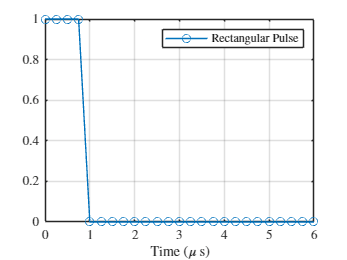


rectp = step(rectwav); s = 25;
nsamp = size(rectp(1:s),1);
t = (0:(nsamp-1))/fs;
plot(t*10^6,real(rectp(1:s)),'-o')
xlabel('Time ($\mu$ s)','interpreter','latex');
legend('Rectangular Pulse','interpreter','latex')
grid; axe()

rect_bw = bandwidth(rectwav)

rect_bw = 9.9931e+05

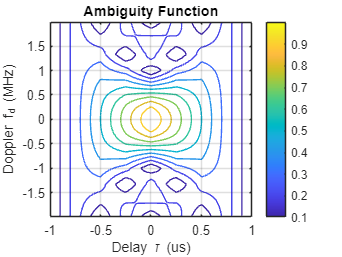


rectsamples = rectwav();
ambgfun(rectsamples,rectwav.SampleRate,rectwav.PRF)
xlim([-tau tau]*1e+6); xline(0); yline(0)

rect_dc = dutycycle(rectwav.PulseWidth,rectwav.PRF)

rect_dc = 0.0100

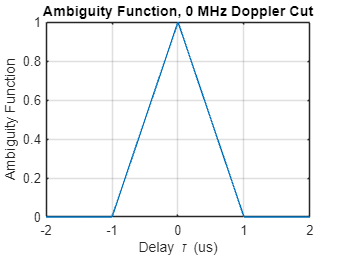


ambgfun(rectsamples,rectwav.SampleRate,...
    rectwav.PRF,'Cut','Doppler')
xlim([-tau tau]*2e+6); xline(0)

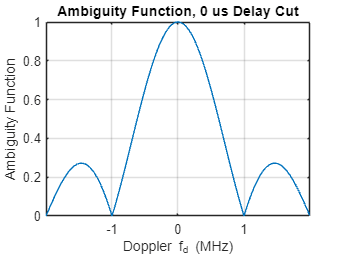

ambgfun(rectsamples,rectwav.SampleRate,...
    rectwav.PRF,'Cut','Delay')
xlim([-bw bw]*2e-6); xline(0)

fc = 1e9;
rect_deltav = dop2speed(1e6,freq2wavelen(fc))/2

rect_deltav = 1.4990e+05

## Linear FM Pulse Waveform

tau_fm = 50/bw;
lfmwav = phased.LinearFMWaveform('SampleRate',...
    fs,'SweepBandwidth',bw,'PRF',prf,...
    'PulseWidth',tau_fm)

lfmwav =   phased.LinearFMWaveform with properties:

                SampleRate: 3.9972e+06
     DurationSpecification: 'Pulse width'
                PulseWidth: 5.0035e-05
                       PRF: 9.9931e+03
     PRFSelectionInputPort: false
            SweepBandwidth: 9.9931e+05
            SweepDirection: 'Up'
             SweepInterval: 'Positive'
                  Envelope: 'Rectangular'
     FrequencyOffsetSource: 'Property'
           FrequencyOffset: 0
              OutputFormat: 'Pulses'
                 NumPulses: 1
             PRFOutputPort: false
    CoefficientsOutputPort: false


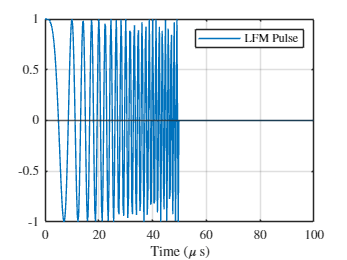

wav = step(lfmwav);
numpulses = size(wav,1);
t = (0:(numpulses-1))/lfmwav.SampleRate;
plot(t*1e6,real(wav))
xlabel('Time ($\mu$ s)', 'interpreter','latex')
grid; yline(0)
legend('LFM Pulse', 'interpreter','latex'); axe();

lfm_dc = dutycycle(lfmwav.PulseWidth,lfmwav.PRF)

lfm_dc = 0.5000


lfm_bw = bandwidth(lfmwav)

lfm_bw = 9.9931e+05

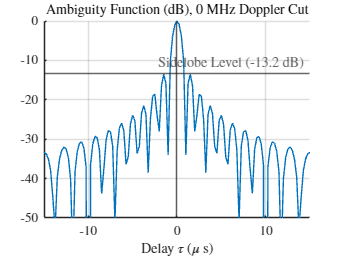


lfmsamples = lfmwav();
[lfmaf_delay,delay] = ambgfun(lfmsamples,...
    lfmwav.SampleRate,lfmwav.PRF,'Cut','Doppler');

figure
hold on
plot(delay*1e6,mag2db(lfmaf_delay))
yline(-13.2,'Label','Sidelobe Level (-13.2 dB)',...
    'interpreter','latex')
grid on
xlabel('Delay $\tau$ ($\mu$ s)',...
    'interpreter','latex')
xlim([-tau_fm tau_fm]*3e5); ylim([-50 0]); xline(0)
title(['Ambiguity Function (dB), 0 MHz ' ...
    'Doppler Cut'], 'interpreter','latex'); axe()

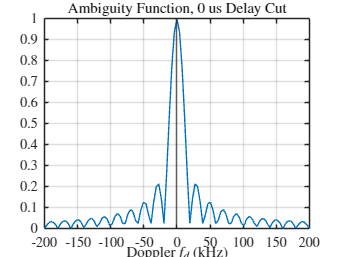

[lfmaf_doppler,doppler] = ambgfun(lfmsamples,...
    lfmwav.SampleRate,lfmwav.PRF,'Cut','Delay');

figure
plot(doppler*1e-3,lfmaf_doppler)
grid on
xlabel('Doppler $f_d$ (kHz)','interpreter',...
    'latex')
xlim([-200 200])
title('Ambiguity Function, 0 us Delay Cut',...
    'interpreter','latex'); axe(); xline(0)

lfm_deltav = dop2speed(20e3,wavelen2freq(fc))/2

lfm_deltav = 2.9979e+03


[lfmaf,delay,doppler] = ambgfun(lfmsamples,...
    lfmwav.SampleRate,lfmwav.PRF);

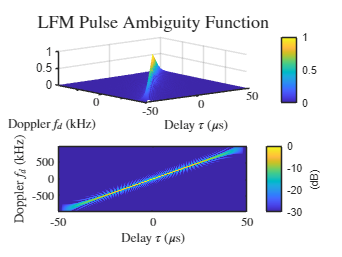

figure
tiledlayout(2, 1)

nexttile
surf(delay*1e6,doppler/1e3,lfmaf,'LineStyle',...
    'none')
xlim([-tau_fm tau_fm]*1e6)
ylim([-bw bw]*1e-3)
colorbar
view([-40,35])
xlabel('Delay $\tau$ ($\mu$s)','interpreter',...
    'latex')
ylabel('Doppler $f_d$ (kHz)','interpreter',...
    'latex'); axe()

nexttile
imagesc(delay*1e6,doppler/1e3,mag2db(lfmaf))
xlim([-tau_fm tau_fm]*1e6)
ylim([-bw bw]*1e-3)
clim([-30 0])
cbar = colorbar;
cbar.Label.String = '(dB)';
axis xy
xlabel('Delay $\tau$ ($\mu$s)','interpreter',...
    'latex')
ylabel('Doppler $f_d$ (kHz)','interpreter',...
    'latex'); axe()

sgtitle(['LFM Pulse Ambiguity' ...
    ' Function'],'interpreter', 'latex')

# Lesser ambiguity in LSM than

# rectangular pulse radar.

# Due to this pulse compression it is

# less susceptible to noise than

# similarly powered rectangular pulse.

# Added benefit of better resolution due

# to small pulsewidth after correlation.

# As a result we obtain defined peaks.

# Doppler affects the matching and is

# depicted in the ambiguity diagrams.

## Barker-Coded Waveform

barkerwav = phased.PhaseCodedWaveform('Code',...
    'Barker','NumChips',7,...
    'SampleRate', fs,'ChipWidth',tau,'PRF',prf)

barkerwav =   phased.PhaseCodedWaveform with properties:

                SampleRate: 3.9972e+06
                      Code: 'Barker'
                 ChipWidth: 1.0007e-06
                  NumChips: 7
                       PRF: 9.9931e+03
     PRFSelectionInputPort: false
     FrequencyOffsetSource: 'Property'
           FrequencyOffset: 0
              OutputFormat: 'Pulses'
                 NumPulses: 1
             PRFOutputPort: false
    CoefficientsOutputPort: false


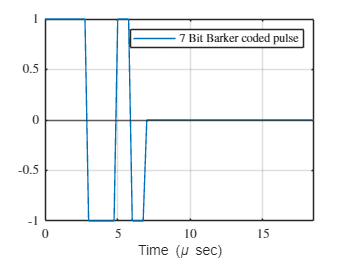

fsB = barkerwav.SampleRate;

up = 75; barkersamples = barkerwav();
nsamp = size(barkersamples(1:up),1);
t = (0:(nsamp-1))/fsB;
plot(t*1e6,barkersamples(1:up))
xlabel('Time (\mu sec)')
axis tight; grid; yline(0)
legend('7 Bit Barker coded pulse',...
    'interpreter', 'latex'); axe()

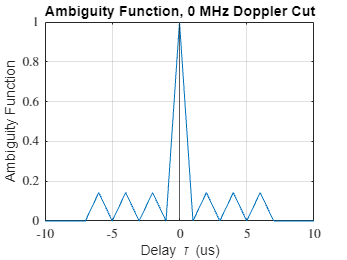

ambgfun(barkersamples,fsB,...
    barkerwav.PRF,'Cut','Doppler')
xlim([-tau tau]*10e6); axe(); xline(0)

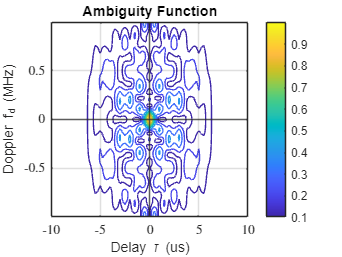

ambgfun(barkersamples,fsB,...
    barkerwav.PRF)
xlim([-tau tau]*10e6); grid
ylim([-bw bw]*1e-6); axe(); xline(0); yline(0)

function axe()
    axes = gca;
    axes.XAxis.TickLabelInterpreter = 'latex';
    axes.YAxis.TickLabelInterpreter = 'latex';
end